1 - Synthèse et transformations du signal porte.

D = 5; %Temps en secondes
N = 2000; %Nombre de points

On retrouve la fonction porte à la fin du document.

t = linspace(-D,D,N);
T = 2;
p = porte(t,T);

On synthétise le signal p.

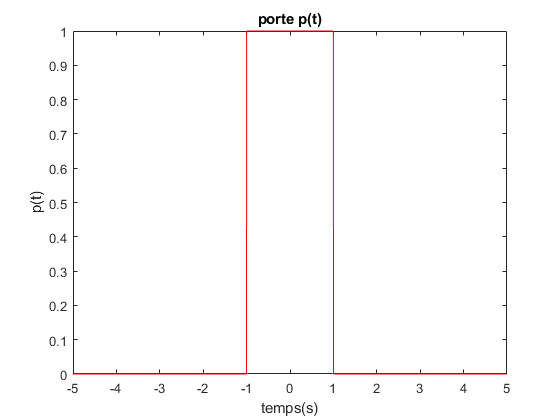

figure(1);
plot(t,p,'r');
title('porte p(t)')
xlabel('temps(s)');
ylabel('p(t)');

On utilise la fonctione de TransFourier.m pour obtenir la transformée de fourier de p(t).

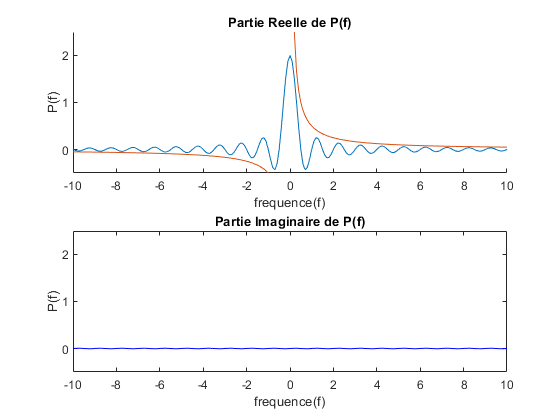

[S,f]=TransFourier(p,t);

figure(2);
subplot(2,1,1);
hold on;
plot(f, real(S));
plot(f,1/2./f); % courbe de la décroissance hyperbolique
axis([-10,10,-0.5,2.5]);
title('Partie Reelle de P(f)');
xlabel('frequence(f)');
ylabel('P(f)');
subplot(2,1,2);
plot(f,imag(S),'b');  % courbe de la partie imaginaire
axis([-10,10,-0.5,2.5]);
title('Partie Imaginaire de P(f)');
xlabel('frequence(f)');
ylabel('P(f)');

P(f) est un nombre complexe étant donné que sa partie imaginaire est non nulle.

L'origine de la transformée de Fourier P(f) à une amplitude de 2. On remarque que c'est la même valeur que la période du signal. Lorsque l'on change la valeur de T, on remarque que l'origine d'amplitude prend également la valeur de T.

La mesure graphique des oscillations secondaires nous donne une fréquence de 1Hz, donc une période de 1s. Ce qui est équivalent à T/2. On trouve une vitesse de décroissance d'amplitude équivalant à la courbe de la décroissance hyperbolique.

On trace maintenant la densité spectrale d'énergie de la fonction porte p(t).

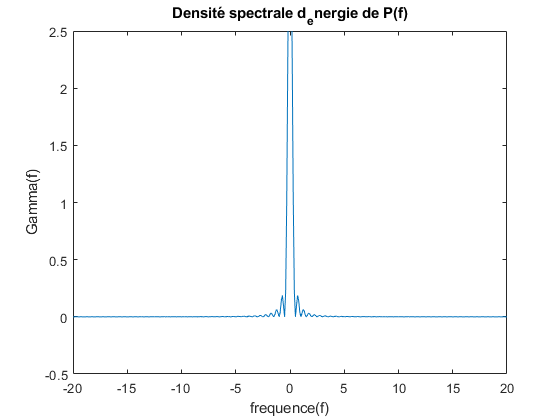

figure(3);
plot(f,abs(S).^2);   % courbe de la densité spectrale
axis([-20,20,-0.5,2.5]);
title('Densité spectrale d_energie de P(f)');
xlabel('frequence(f)');
ylabel('Gamma(f)');

Par lecture graphique, la largeur du lobe primaire de la densité spectrale d'énergie de la fonction porte p(t) est de 1Hz. Tandis que celle des lobes secondaires est de 0.5Hz.

C'est cohérant avec les valeurs théorique étant donné que l'on effectue le calcul suivant : Es = Ao^2*T/2. Et puisque Ao = 1 et T = 2, alors Es = 1 Hz, la largeur du lobe primaire.

On synthétise maintenant le signal p(t-t0).

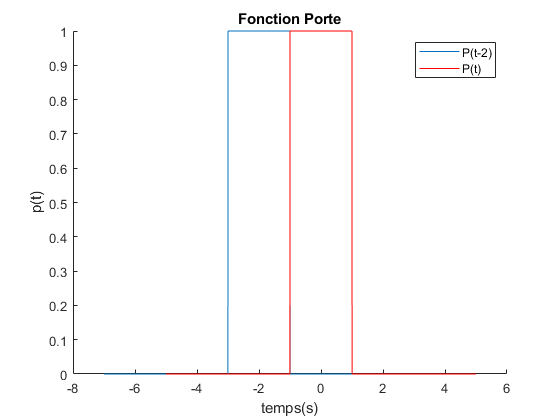

figure(4);
hold on 
plot(t-2,p);  % fonction porte translatée de 2
plot(t,p,'r');  % fonction porte centrée en 0
title('Fonction Porte');
xlabel('temps(s)');
ylabel('p(t)');
legend('P(t-2)','P(t)');

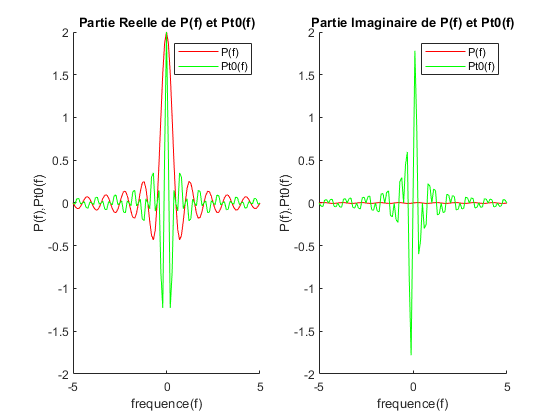

[P,f]=TransFourier(p,t-2);

figure(5);
subplot(121);
hold on;
plot(f,real(S),'r');   %Partie réelle de P(f)
plot(f,real(P),'g');    % Partie réelle de Pt0(f)
axis([-5,5,-2,2]);
title('Partie Reelle de P(f) et Pt0(f)');
xlabel('frequence(f)');
ylabel('P(f),Pt0(f)');
legend('P(f)','Pt0(f)');

subplot(122);
hold on;
plot(f,imag(S),'r');   %Partie imaginaire de P(f)
plot(f,imag(P),'g');   %Partie imaginaire de Pt0(f)
axis([-5,5,-2,2]);
title('Partie Imaginaire de P(f) et Pt0(f)');
xlabel('frequence(f)');
ylabel('P(f),Pt0(f)');
legend('P(f)','Pt0(f)');

Comme la fonction porte n'est pas symétrique, alors la fonction porte, qui comporte un retard, va se retrouver à contenir une partie imaginaire. Ainsi, le signal P_t0(f) n'est pas réel.

On synthétise maintenant le signal p_a(t).

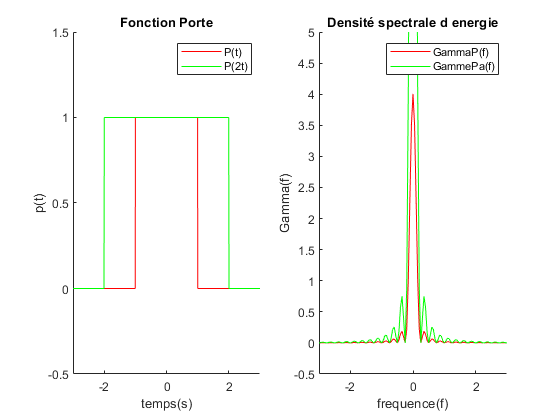

a = 2*t;
[Q,f]=TransFourier(p,a);   %Transformée de Fourier du signal changement d'échelle

figure(6);
subplot(121);
hold on;
plot(t,p,'r');   %fonction porte 
plot(2*t,p,'g');    %fonction porte avec changement d'echelle
title('Fonction Porte');
xlabel('temps(s)');
ylabel('p(t)');
legend('P(t)','P(2t)');
axis([-3,3,-0.5,1.5]);

subplot(122);
hold on;
plot(f,abs(S).^2,'r');  % densité d'energie du signal P(f)
plot(f,abs(Q).^2,'g');   % densité d'energie du signal Pa(f)
title('Densité spectrale d energie');
xlabel('frequence(f)');
ylabel('Gamma(f)');
legend('GammaP(f)','GammePa(f)');
axis([-3,3,-0.5,5]);

On observe ici une fonction porte deux fois plus large que l'autre. Ainsi que des densités spectrales aux durées et aux largeurs de bandes équivalentes. Cependant, la densité spectrale de la fonction porte deux fois plus large que l'original à une amplitude à la source bien plus grande. Effectivement, il a une amplitude de 16 alors que l'original reste à 4 d'amplitude. Cela s'explique par la relation de la densité d'energie, où l'amplitude est multiplié au carré. Ainsi, 2^2 = 4, donc la densité spectrale de p_a(t) est 4 fois supérieur à celle de p(t). Ainsi, prendre une part plus grande du signal de départ permettra une augmentation de la densité spectrale.

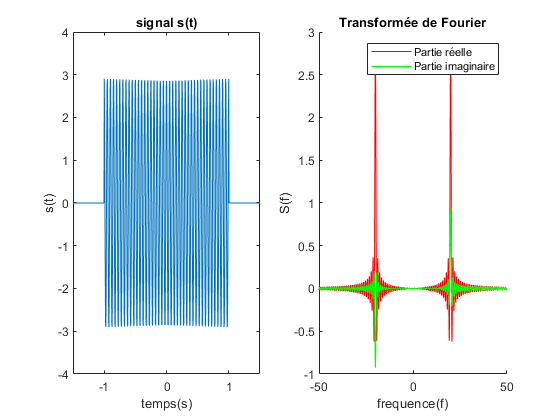

A = 3;
f_0 = 20;

s=p.*(A*cos(2 * f_0*pi*t));    % création du signal s(t)
[S,f]=TransFourier(s,t);   % Transformée de fourier de la fonction s(t)

figure(7);
subplot(121);
plot(t,s);    % courbe s(t)
title('signal s(t)');
xlabel('temps(s)');
ylabel('s(t)');
axis([-1.5,1.5,-4,4]);

subplot(122);
hold on;
plot(f,real(S),'r');   % affichage de la partie reelle de S(f)
plot(f,imag(S),'g');   % affichage de la partie imaginaire de S(f)
title('Transformée de Fourier');
xlabel('frequence(f)');
ylabel('S(f)');
legend('Partie réelle','Partie imaginaire');
axis([-50,50,-1,3]);

On remarque que la transformée de fourier de notre signal s est complexe. Car la partie imaginaire de S(f) n'est pas nulle. On remarque que la partie réelle est symétrique tandis que la partie imaginaire est antisymétrique. Cela s'explique sur la théorique étant donné que la partie réelle est composé d'un consinus et la partie imaginaire d'un sinus.

On peut estimer l'énergie du signal s à partir de sa représentation s(t) comme étant Es = 3. A partir de la représentation temporelle, on trouve sqrt(sqrt(8)²+1) = 3. Ainsi, on voit que l'on se trouve devant le Théorème de Parseval.

D'un point de vue très général, l'intérêt d'étudier la porte rectangulaire p(t) est que c'est un signal facilement modélisable. De plus, cela va être une alternative pour définir les signaux sur un intervalle donné, étant donné qu'il est courant de multiplier les signaux par une fonction porte pour les délimiter. Ainsi, la fonction porte va se révéler être une sorte de témoin pour la suite.

La fonction porte est : 

function y=porte(x,T) 
    y=abs(x)<T/2;
    end